# 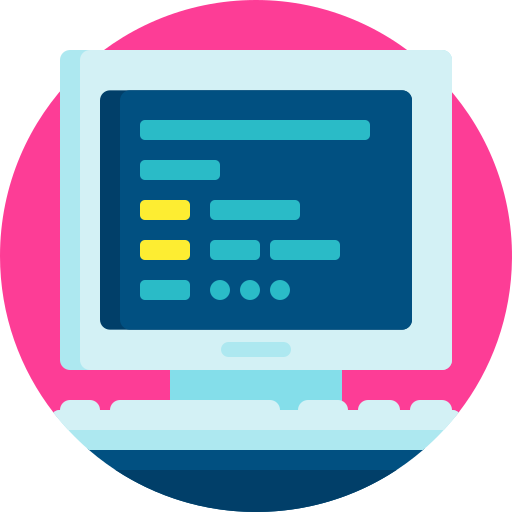

# Virtual Lab 2: The armature-controlled DC motor

**Chapter 3-4**

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on Right`.

- This script has been sectioned off — you can use `Run Section `(CMD/CNTL+ENTER) instead of` Run `when in a particular section. This will only evaluate code in the section. 

- This virtual lab requires the following `MATLAB` toolboxes: Control Systems Toolbox, Symbolic Math Toolbox.

- You can use the `help` function to get information on a function within the `MATLAB Command Window`, e.g. `help laplace`.

## DC motor block diagram

The figure below shows the block diagram of an armature-controlled DC motor where:

- $v(t)$ is the controllable input voltage, measured in volts $[V]$

- $\tau_L(t)$ is the torque load (external disturbance), measured in Newton-metres $[N.m]$

- $\Omega(t)$ is the angular velocity of the motor shaft, measured in radians per second $[rad/s]$

- $\tau(t)$ is the applied torque, measured in Newton-metres $[N.m]$

- $i(t)$ is the armature current, measured in Amperes $[A]$

- $R$ is the armature resistance, measured in Ohms $[\Omega]$

- $L$ is the armature inductance, measured in Henries $[H]$

- $K_t$ is the torque constant, measured in Newton-metres per Ampere $[N.m/A]$

- $K_e$ is the back-emf constant, measured in volts per radian per second $[V.s/rad]$

- $J$ is the moment of inertia of the motor, measured in kilogram-metres squared $[kg.m^2]$

- $B$ is the damping coefficient, measured in Newton-metres per radian per second $[N.m.s/rad]$

Note that $K_e=K_t=K$.

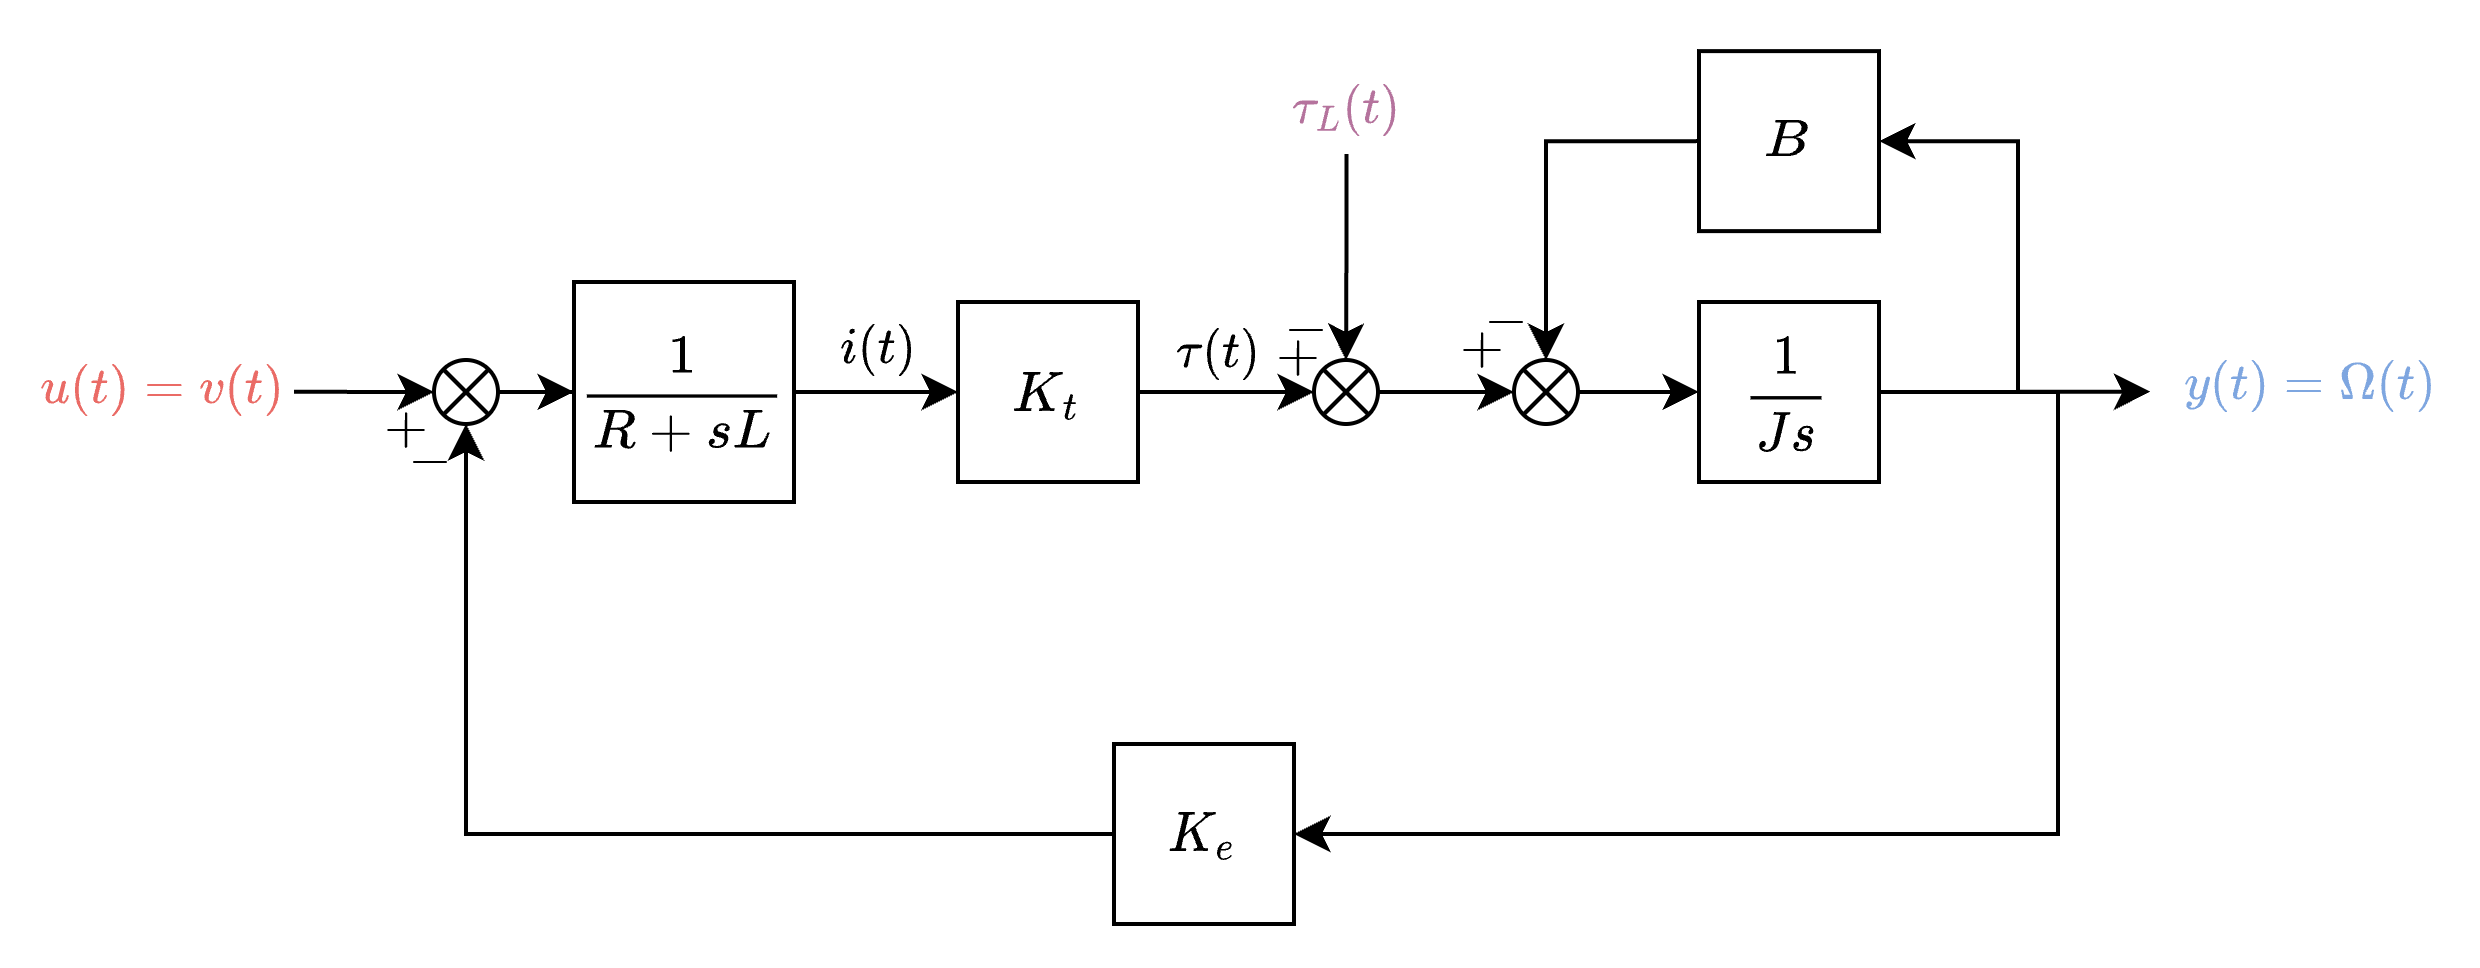

*Figure 1: Full block diagram of armature-controlled DC motor*

Imagine that we are interested in controlling the angular velocity of the DC motor, $y(t)=\Omega(t)$, using the input voltage, $u(t)=v(t)$, but we have no control over when the torque load, $\tau_L(t)$, acts on our system, or what kind of signal profile and magnitude it will take. 

Note that this block diagram of our DC motor is still describing an *open-loop system* in terms of us regulating the angular velocity — the apparent feedback loop is not aiding us in setting the achieved angular velocity and is rather a consequence of the underlying differential equations that describes how DC motors work.

#### **  Question 1: Determine the transfer behaviour from the motor current, **$I(s)$, to the system output, $Y(s)$. Provide your answer as a ratio of polynomials.

*Hint: set *$\tau_L(t)=0$ when considering the two internal signals.

#### **  Question 2: Determine the transfer behaviour from input voltage, **$U(s)$, to the motor current, $I(s)$. Provide your answer as a ratio of polynomials.

*Hint: set *$\tau_L(t)=0$ when considering the internal and external signal.

#### **  Question 3: Determine the transfer behaviour from **$U(s)$ to $Y(s)$.

*Hint: your answers to Question 1 and Question (if correct) can be used to answer this question in a single step.*

We can use block diagram algebra to reduce the above model into a simpler form that can be used to assess the individual effects of $v(t)$ and $\tau_L(t)$ on $\Omega(t)$. Specifically, we can find 

$\lim_{T_L(s)\rightarrow 0}\frac{\Omega(s)}{V(s)}=P_V(s) ~~  [ \frac{rad/sec}{V} ]$, 

which describes the transfer behaviour from the input voltage to the motor angular velocity, and 

$\lim_{V(s)\rightarrow 0}\frac{\Omega(s)}{T_L(s)}=P_T(s)  ~~  [ \frac{rad/sec}{Nm} ]$, 

which describes the transfer behaviour from the load torque to the motor angular velocity, where $T_L(s)=\mathcal{L}\{\tau_L(t)\}$. Note the units of measurement for the particular transfer function, which relate to the input and output signals of interest. 

A compact description of the angular velocity in the $s$-domain follows as 

$\Omega(s)=P_V(s)V(s)+P_T(s)T_L(s)$, 

as shown in block diagram form below (*pay special attention to the comparator signs)*.

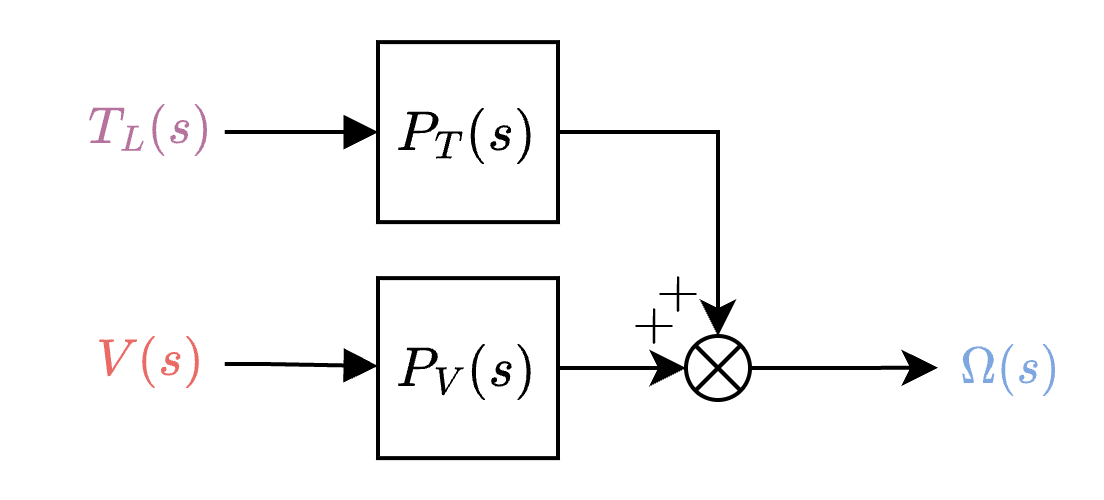

*Figure 2: Simplified block diagram of armature-controlled DC motor*

#### **  Question 4: Determine** $P_V(s)$ from Figure 1.

#### **  Question 5: Determine** $P_T(s)$ from Figure 1.

## Time-domain behaviour 

We can define our Laplace transfer functions in `MATLAB` in order to assess the transfer behaviour of our motor. The adjustable (for sake of demonstration) motor parameters are shown below:

R = 4.6; %Motor armature resistance, in Ohms
L = 0.021; %Motor inductance, in Henries
K = 4; %Motor torque cosntant, in N.m/A
J = 0.35; %Motor inertia, in kg.m^2
B = 2; %Damping factorN.m.s

hold  on;   %hold on - keep overlaying plots on same figure. hold off - only one plot at a time.

####   **Task:** Use your answers to **Question 4** and **Question 5** to define the [MATLAB transfer function](https://www.mathworks.com/help/control/ref/tf.html) for $P_V(s)$ and $P_T(s)$ in the code block below using the symbols above.

s = tf('s');    %define Laplace variable, s
Pv = ?;  %transfer behaviour from input voltage to angular velocity
Pt = ?;    %transfer behaviour from load torque to angular velocity

Ignoring the load torque for now (by setting $\tau_L(t)=0$) , we can assess the transfer behaviour from the voltage input to the angular velocity of the motor by applying a perturbation. We will apply a unit [`step`](https://www.mathworks.com/help/control/ref/lti.step.html) of 1 Volt to our DC motor to see how it behaves.

step(Pv) % apply a unit step input to the DC motor system. This generates a step response plot.

Play around with the sliders to get a feel for how the parameters affect the relationship between the applied voltage and resulting angular velocity. Think about how the physical elements (such as the inertia of the motor) would affect the system and compare it with the simulation results. 

## Final-value theorem

As we will learn in a later chapter, the final (or steady-state) value of a system response, $y(t)$, can be determined by

$y(\infty)=\lim_{s\rightarrow 0}sY(s)$.

This means that if a step input signal of $a$ volts is applied to our motor (with no disturbances present), then at steady-state, the time-domain angular velocity will be 


$$\begin{array}{rl}
\Omega(\infty)
&=\lim_{s\rightarrow 0}s\Omega(s),\\
&=\lim_{s\rightarrow 0}sP_V(s)\frac{a}{s},\\
&=a\lim_{s\rightarrow 0}P_V(s).
\end{array}$$


Importantly, this only applies to system responses that are bounded (do not shoot off to infinity).

#### **  Question 6: Determine the algebraic steady-state value of the motor angular velocity, **$y(\infty)=\Omega(\infty)$, as a result of a unit step input voltage, $V(s)=1/s$, when $T_L(s)=0$.

*Hint: You can confirm the mathematical result for a set of motor parameters using the step function above.*

Lets now assume that the motor parameters are elements that we cannot alter in any way (although you were initially allowed to mess around with them to see how the parameters change the velocity response). The only signal that we actually have control over is the input voltage. Setting the motor parameters to constant values of

R = 0.1; 
L = 0;
K = 1;
J = 5;
B = 1;

we can adjust the input voltage such that the output behaves in the way that we want (within reason). We can scale our input step signal (setting $a$) by multiplying the argument inside the [`step`](https://www.mathworks.com/help/control/ref/lti.step.html) function (as shown in the code block below), and based on the linearity property, this will also scale our output accordingly.

Pv = ?;  %transfer behaviour from input voltage to angular velocity
a = 15;  %voltage magnitude of step input
figure 
step(Pv*a) %step the DC motor system with a step input of a Volts.

#### **  Question 7: Using final-value theorem, w**hat input voltage is required to achieve a motor angular velocity of 100 rad/s?

%Use this code block if required for computations.


*Hint: You can confirm your answer using the simulation code above.*

## Open-loop disturbance rejection

The open-loop relationship between the input voltage and output angular velocity is convenient and simple (assuming we know exactly what our motor parameters are), but so far we have been ignoring load torque — we have effectively set $\tau_L(t)=0$ in our system. 

We can demonstrate the effect that the load torque will have on our open-loop system using the code below. The simulation code applies the same input voltage as before to the motor, but in addition, a load torque of $200$ Nm is applied to the system at time $t=5$ seconds. 

####   **Task:** Fill in the missing transfer function values in the code block below and use your answer from Question 7 for the $a$ value.

Pv = ?;  %transfer behaviour from input voltage to angular velocity
Pt = ?;    %transfer behaviour from load torque to angular velocity
a = 1;  %voltage magnitude of step input

t = 0:1e-2:10;

[yv,~] = step(Pv*a,t);

tau = 200/s*exp(-s*5);    

Invalid expression. Check for missing or extra characters.

[yt,~] = impulse(Pt*tau,t);

y = yv+yt;

figure 
plot(t,y,lineWidth=2) %output response of motor to step 

What you should notice is that when the disturbance is applied at $t=5$ seconds, the output speed of the motor is reduced as a result of the reduced net torque. So even if with the correct input voltage from **Question 7**, the load torque ends up ruining our simple input-output relationship from before. Because we cannot measure the load torque, we can never know what amount of load torque to compensate for (the torque may act at different time, or with a different magnitude). In other words, we can never guarantee that our motor speed will be correct when subjected to disturbances.

#### **  Question 8: Based on the information above, what is** $T_L(s)$?

## Closed-loop disturbance rejection

The open-loop system is sensitive to unmeasurable disturbances, which means that we cannot guarantee our motor velocity will match our desired velocity. The solution to this problem is to make use of feedback control, as shown in the figure below, where $G(s)$ serves as our feedback controller to be designed, $R(s)$ is the desired velocity, and $E(s)$ is the tracking error.

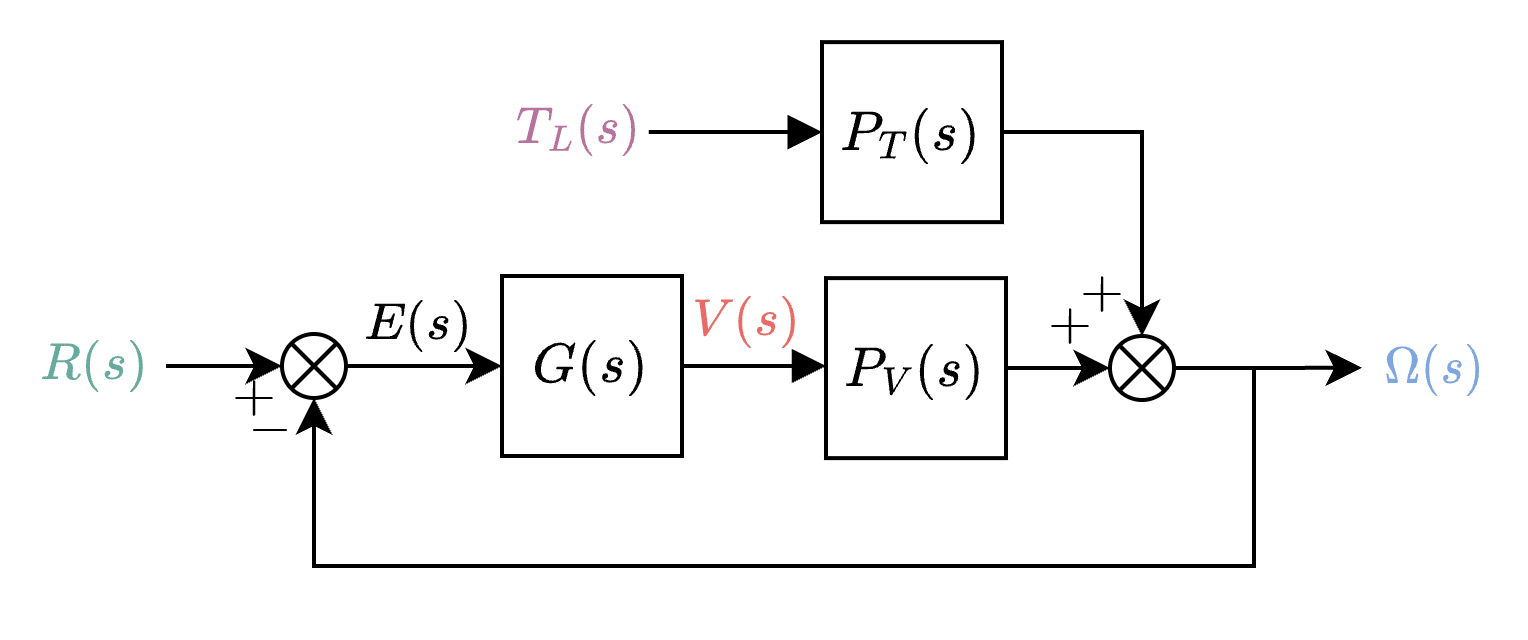

We will not worry about the finer details just yet, but the objective of our feedback control scheme is to make $e(t)=r(t)-y(t)$ sufficiently small. To keep things simple, we will use the most rudimentary feedback control law, namely a proportional controller, which has the form $G(s)=k$. As the name suggests, the voltage applied to our motor will be directly proportional to the error signal $e(t)$, 

$v(t)=ke(t)$,

and this will help to reduce disturbance effects on our system.

#### **  Question 9: Using the block diagram above, determine the transfer behaviour, **$Q_R(s)$,** from **$R(s)$ to $\Omega(s)$, as a function of $P_V(s)$, $P_T(s)$, and $G(s)$.

#### **  Question 10: Using the block diagram above, determine the transfer behaviour, **$Q_T(s)$,** from **$T_L(s)$ to $\Omega(s)$, as a function of $P_V(s)$, $P_T(s)$, and $G(s)$.

####   **Task:** Complete the code below using your answers from Question 9 and Question 10. 

Pv = ?;  %transfer behaviour from input voltage to angular velocity
Pt = ?;    %transfer behaviour from load torque to angular velocity

k = 1;

G = k;
Qr = ?; %transfer behaviour from reference velocity to output velocity
Qt = ?;   %transfer behaviour from load torque to output velocity

r = 11;  %desired motor velocity

t = 0:1e-3:0.2;

[yv,~] = step(Qr*r,t);

tau = 200/s*exp(-s*0.1);    
[yt,~] = impulse(Qt*tau,t);

y = yv+yt;

figure, hold on
plot(t,y,lineWidth=2) %output response of motor to step 
step(r+0*s,t)   %plots the reference speed

Assuming you have completed the code correctly, you should see that choosing a sufficiently large $k$ appears to remove the effect of the disturbance on the closed-loop system. Not only that, but the closed-loop response settles quicker as the gain increases. It seems that high feedback gain is solving all our problems! This is not quite true, as we have neglected to consider various other real-world effects, such as sensor noise, input limits, and general stability, all of which will limit how large we can make our loop gain — more on this in future assessments.

#### **  Question 11: Rename your completed live script to include your student number (e.g. VirtualLab1_SMTJOH999.mlx) and submit it as your answer to Question 11.**

***This concludes Virtual Lab 2. ***